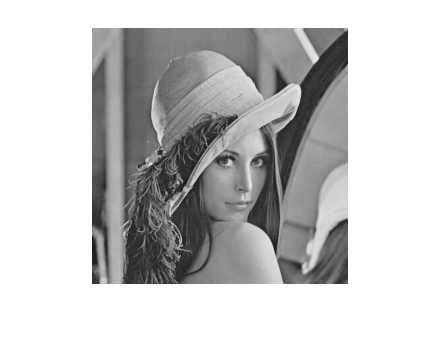

A=imread('/home/amrit/Documents/EE5175/EE5175_ISP_Lab1/Lab1/lena_translate.pgm');
B=zeros(size(A));
C=zeros(size(A));

tx=3.75;
ty=4.3;

for i=1:256
    for j=1:256
        if (i-5>=1 && j-5>=1 && i-5<=size(A,1) && j-5<=size(A,2));
             
        B(i,j)=A(i-5,j-5);
        end
    end
end
imshow(A)

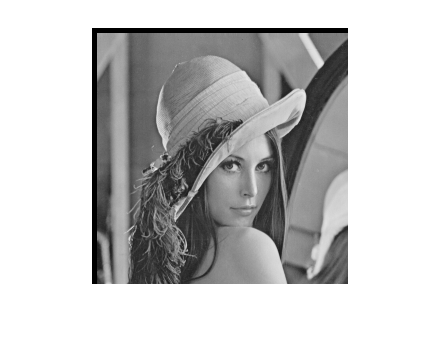

imshow(B,[0 255])

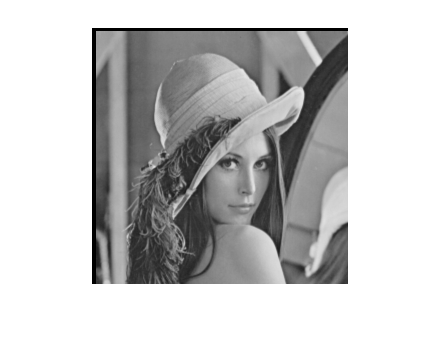


for i=1:256
    for j=1:256
        a=tx-floor(tx);
        b=ty-floor(ty);
        
       
        if (i-floor(tx)>=1 && j-floor(ty)>=1 &&  i-floor(tx)<=size(A,1) && j-floor(ty)<=size(A,2));
            C(i,j)=(1-a)*(1-b)*A(i-floor(tx),j-floor(ty))+a*(1-b)*A(i-floor(tx),j-floor(ty)+1)+b*(1-a)*A(i-floor(tx)+1,j-floor(ty))+a*b*A(i-floor(tx)+1,j-floor(ty)+1);  
        end
             
        
        
        
    end
end

imshow(C,[0 255])